% Вхідні параметри
G_m = 2.5;   
C_m = 2.1;   
C_g = 1.05;  
kk = 0.723;
kr = 4.835e-11;
T1g = 1773.15; 
T2m0 = 533.15;  
T3m0 = 623.15;  
T2g0 = 1273.15; 
T3g0 = 973.15;  
rho = 900;

% Значення для графіків
G_g_values = linspace(0.1, 1.5, 20); 
T1m_values = linspace(423.15, 573.15, 20); % від 150°C до 300°C
T1m_fixed = 473.15; % для Gг→T3м (200°C)
Gg_fixed = 1.26;     % для T1м→T3м

% Система рівнянь
fun = @(x, G_g, T1m) [
    G_m * C_m * (T1m - x(1)) + kk * (x(4) - (x(1) + T1m) / 2);
    G_m * C_m * (x(1) - x(2)) + kr * (x(3)^4 - ((x(1) + x(2)) / 2)^4);
    G_g * C_g * (T1g - x(3)) - kr * (x(3)^4 - ((x(1) + x(2)) / 2)^4);
    G_g * C_g * (x(3) - x(4)) - kk * (x(4) - (x(1) + T1m) / 2)
];

T3m_Gg = zeros(size(G_g_values));
T3m_T1m = zeros(size(T1m_values));

% Канал Gг → T3м
for i = 1:length(G_g_values)
    G_g = G_g_values(i);
    x0 = [T2m0, T3m0, T2g0, T3g0]; 
    x = fsolve(@(x) fun(x, G_g, T1m_fixed), x0); 
    T3m_Gg(i) = x(2) - 273.15; % в Цельсіях
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 


% Канал T1м → T3м
for i = 1:length(T1m_values)
    T1m = T1m_values(i);
    x0 = [T2m0, T3m0, T2g0, T3g0]; 
    x = fsolve(@(x) fun(x, Gg_fixed, T1m), x0); 
    T3m_T1m(i) = x(2) - 273.15; % в Цельсіях
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

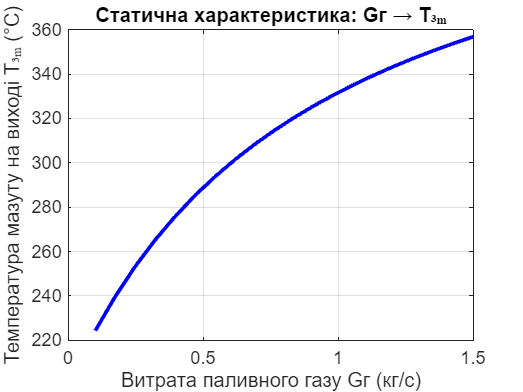


% Графік Gг → T3м
figure;
plot(G_g_values, T3m_Gg, 'b-', 'LineWidth', 2);
xlabel('Витрата паливного газу Gг (кг/с)');
ylabel('Температура мазуту на виході T₃ₘ (°C)');
title('Статична характеристика: Gг → T₃ₘ');
grid on;

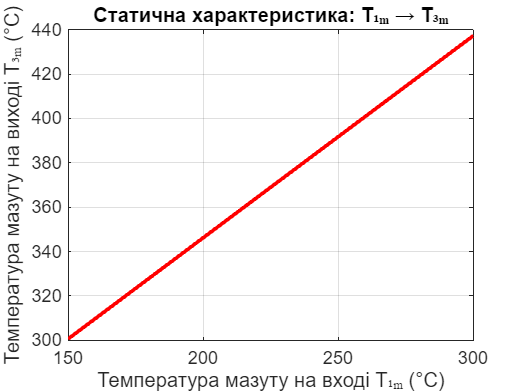


% Графік T1м → T3м
figure;
plot(T1m_values - 273.15, T3m_T1m, 'r-', 'LineWidth', 2);
xlabel('Температура мазуту на вході T₁ₘ (°C)');
ylabel('Температура мазуту на виході T₃ₘ (°C)');
title('Статична характеристика: T₁ₘ → T₃ₘ');
grid on;